# Figure of regularized PCA performance for all Ac group depending on #PC

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

PLim = 0.001;
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UGroup = unique(TmicAll4);
Mat_PCC_mean = nan((length(UGroup)+1),2);
Mat_PCC_std = nan((length(UGroup)+1),2);
NumSig = nan(length(UGroup)+1,2); % Column 1 number of permutation sets significanty different from observed data Column 2: total number of tests
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_AcGroup%d.mat', GR)),  'PC_val', 'NPC_opt_all','PCC_all_mean_std', 'PCCperm_all_mean_std','PFisher');
    NPC_opt_ind = find(PC_val==NPC_opt_all);
    Mat_PCC_mean(GR,1) = PCC_all_mean_std(NPC_opt_ind,1);
    Mat_PCC_mean(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,1);
    Mat_PCC_std(GR,1) = PCC_all_mean_std(NPC_opt_ind,2);
    Mat_PCC_std(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,2);
    NumSig(GR,1) = sum(PFisher<PLim);
    NumSig(GR,2) = length(PFisher);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_AllCalls.mat'), 'PC_val', 'NPC_opt_all','PCC_all_mean_std', 'PCCperm_all_mean_std', 'PFisher')
GR=5;
NPC_opt_ind = find(PC_val==NPC_opt_all);
Mat_PCC_mean(GR,1) = PCC_all_mean_std(NPC_opt_ind,1);
Mat_PCC_mean(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,1);
Mat_PCC_std(GR,1) = PCC_all_mean_std(NPC_opt_ind,2);
Mat_PCC_std(GR,2) = PCCperm_all_mean_std(NPC_opt_ind,2);
NumSig(GR,1) = sum(PFisher<PLim);
NumSig(GR,2) = length(PFisher);

% Number of calls in each group
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'),'MicAudioGood', 'BatID');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
IndMicAudioGood = find(MicAudioGood01);
% Get the vector SexDeaf
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
SexDeaf =  cell(length(BatID),1);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
    end

end
SexDeafMic = SexDeaf(IndMicAudioGood);

Figure of all results

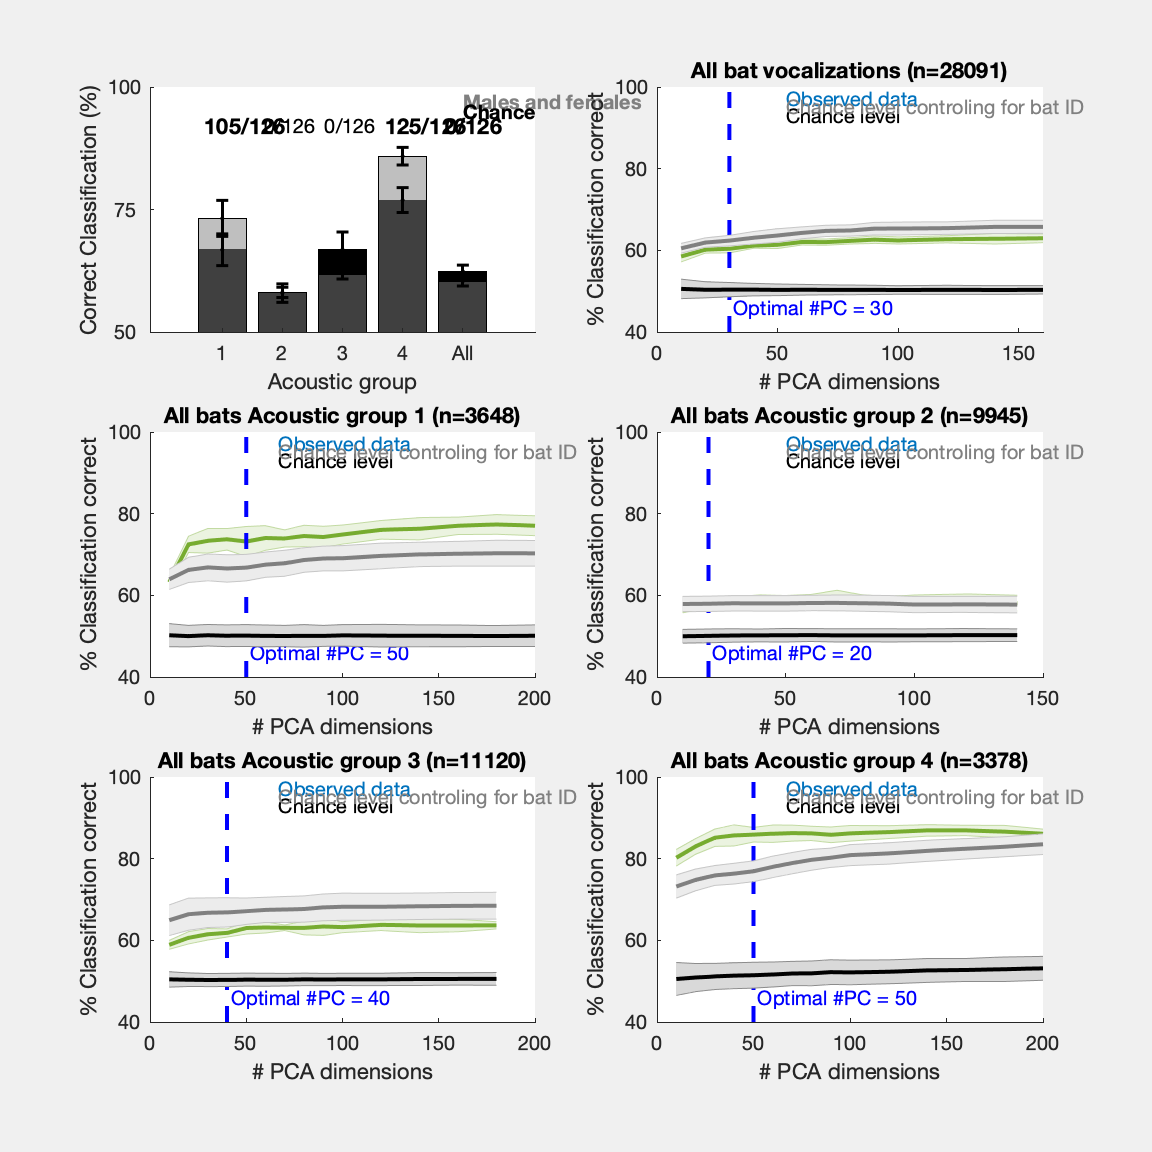

FIG = figure(1);
clf
set(gcf,'Visible','on')

% Barplot
subplot(3,2,1)
GR = length(UGroup);
X = 1:GR+1;
B1=bar(X,Mat_PCC_mean(:,2),'FaceColor', [0 0 0]);
hold on
B2=bar(X,Mat_PCC_mean(:,1));
B2.CData = repmat([0.5 0.5 0.5],5,1);
B2.FaceColor = 'flat'; B2.FaceAlpha = 0.5;
hold on
errorbar(X,Mat_PCC_mean(:,2),Mat_PCC_std(:,2), Mat_PCC_std(:,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(:,1),Mat_PCC_std(:,1), Mat_PCC_std(:,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
hold on
text(5,97,'Males and females','color',[0.5 0.5 0.5], 'FontWeight', 'bold')
hold on
text(5,95,'Chance','color','k', 'FontWeight', 'bold')
hold on

for GR=1:length(UGroup)+1
    if GR==1 || GR==4 || GR==5
        text(GR-0.3,92,sprintf('%d/%d',NumSig(GR,1), NumSig(GR,2)), 'FontWeight','bold', 'FontSize',11)
    else
        text(GR-0.3,92,sprintf('%d/%d',NumSig(GR,1), NumSig(GR,2)))
    end
    hold on
end
hold off

% Line plot of performance across PCA Dim for all
subplot(3,2,2);
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_AllCalls.mat'),  'PC_val', 'NPC_opt_all','L_all', 'PCC_all_mean_std', 'Lperm_all', 'PCCperm_all_mean_std', 'Lrand_all', 'PCCrand_all_mean_std', 'PC_DF_all')
PC_val_plot = PC_val(1:size(PCCrand_all_mean_std,1));
shadedErrorBar(PC_val_plot, PCC_all_mean_std(1:length(PC_val_plot),1),PCC_all_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(5,:), 'LineWidth',2})
xlabel('# PCA dimensions')
ylabel('% Classification correct')
set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
hold on
V = vline(NPC_opt_all, 'b--', sprintf('Optimal #PC = %d', NPC_opt_all));
V.LineWidth = 2;
hold on
shadedErrorBar(PC_val_plot, PCCrand_all_mean_std(:,1),PCCrand_all_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
hold on
shadedErrorBar(PC_val_plot, PCCperm_all_mean_std(:,1),PCCperm_all_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
hold off
XLim = get(gca,'XLim');
text(XLim(2)/3,97, 'Observed data', 'Color', ColorCode(1,:))
text(XLim(2)/3,93, 'Chance level', 'Color', 'k')
text(XLim(2)/3,95, 'Chance level controling for bat ID', 'Color', [0.5 0.5 0.5])
title(sprintf('All bat vocalizations (n=%d)', length(TmicAll4)))
box off


% Line plots of performance accross PCA Dim
for GR=1:4
    subplot(3,2,GR+2);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_AcGroup%d.mat', GR)),  'PC_val', 'NPC_opt_all','L_all', 'PCC_all_mean_std', 'Lperm_all', 'PCCperm_all_mean_std', 'Lrand_all', 'PCCrand_all_mean_std', 'PC_DF_all')
    PC_val_plot = PC_val(1:size(PCCrand_all_mean_std,1));
    shadedErrorBar(PC_val_plot, PCC_all_mean_std(1:length(PC_val_plot),1),PCC_all_mean_std(1:length(PC_val_plot),2),{'-','color',ColorCode(5,:), 'LineWidth',2})
    xlabel('# PCA dimensions')
    ylabel('% Classification correct')
    set(gca, 'YLim', [40 100])
%     hold on
%     H=hline(50, 'k--','Chance level');
%     H.LineWidth = 2;
    hold on
    V = vline(NPC_opt_all, 'b--', sprintf('Optimal #PC = %d', NPC_opt_all));
    V.LineWidth = 2;
    hold on
    shadedErrorBar(PC_val_plot, PCCrand_all_mean_std(:,1),PCCrand_all_mean_std(:,2), {'-','Color','k', 'LineWidth',2})
    hold on
    shadedErrorBar(PC_val_plot, PCCperm_all_mean_std(:,1),PCCperm_all_mean_std(:,2), {'-', 'Color', [0.5 0.5 0.5], 'LineWidth',2})
    hold off
    XLim = get(gca,'XLim');
    text(XLim(2)/3,97, 'Observed data', 'Color', ColorCode(1,:))
    text(XLim(2)/3,93, 'Chance level', 'Color', 'k')
    text(XLim(2)/3,95, 'Chance level controling for bat ID', 'Color', [0.5 0.5 0.5])
    title(sprintf('All bats Acoustic group %d (n=%d)', GR, sum(TmicAll4==GR)))
    box off
%     title(sprintf('# Significant exact Fisher test (obs vs perm) at optimal #PC: %d/%d', sum(PFisher_males<PLim), length(PFisher_males)))
end





FIG.PaperOrientation = 'landscape';
FIG.Units = 'inches';
FIG.Position(3:4) = [8 8];
FIG.PaperSize = [8 8];
print(FIG,fullfile(Path2Paper,'SupFigure10_PCADFA_All_TmicAll4.pdf'),'-dpdf','-fillpage')

Just one plot of Correct classification above chance level for each acoustic group

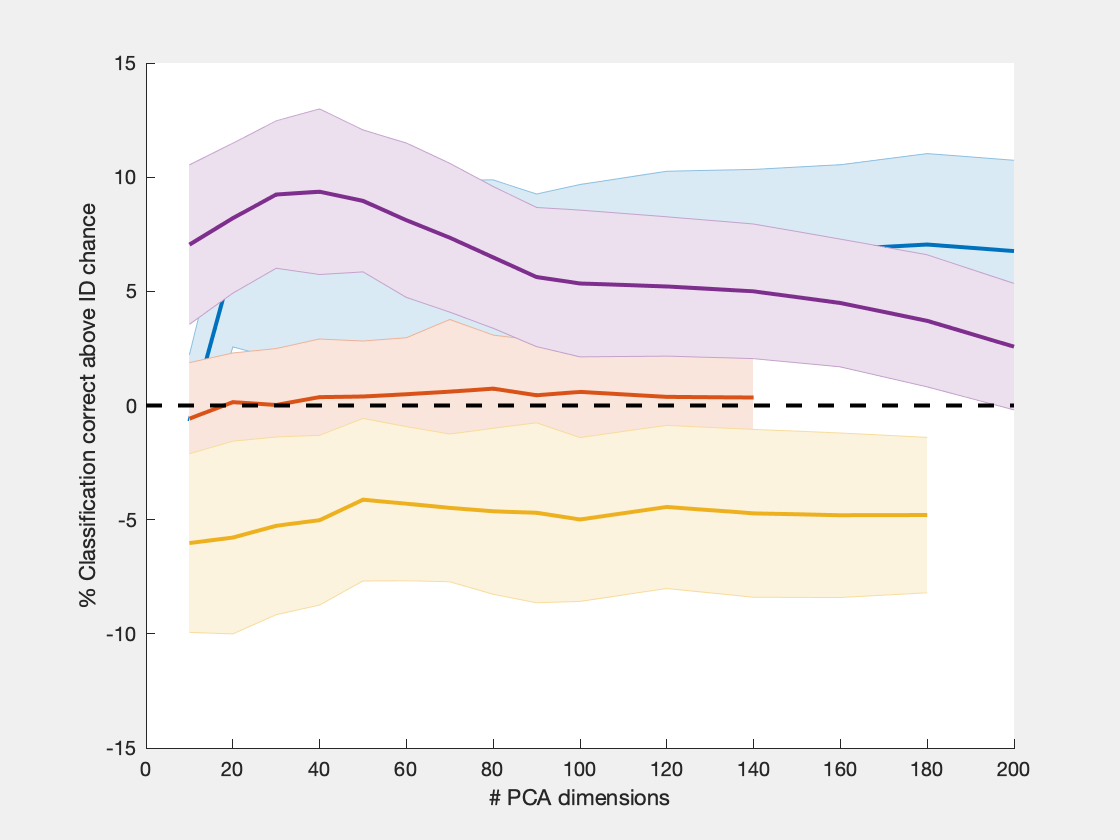

FIG2 = figure(2);
clf
set(gcf,'Visible','on')

for GR=1:4
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_AcGroup%d.mat', GR)),  'PC_val', 'NPC_opt_all','L_all', 'PCC_all_mean_std', 'Lperm_all', 'PCCperm_all_mean_std', 'Lrand_all', 'PCCrand_all_mean_std', 'PC_DF_all')
    PC_val_plot = PC_val(1:size(PCCrand_all_mean_std,1));
    PCC_aboveChance_mean = PCC_all_mean_std(1:length(PC_val_plot),1)-PCCperm_all_mean_std(:,1);
    PCC_aboveChance_std = (PCC_all_mean_std(1:length(PC_val_plot),2).^2+ PCCperm_all_mean_std(:,2).^2).^0.5;
    hold on
    shadedErrorBar(PC_val_plot, PCC_aboveChance_mean,PCC_aboveChance_std,{'-','color',ColorCode(GR,:), 'LineWidth',2})
    xlabel('# PCA dimensions')
    ylabel('% Classification correct above ID chance')
    set(gca, 'YLim', [-15 15])
end
H=hline(0,'k--');
H.LineWidth = 2;
hold off